% paths
path = ("C:\Users\BrainMaker\commsubspace\hash");
addpath(path)

addpath(genpath('utils')); % all folders in utils added, including semedo code

% load
load("Megatable.mat");

% query from the folder
%  key = hash; % to examine the current result
key = "f1876f1";
key = "5295fea";

cd(path)
filename = strcat(key,".mat");
load(key+".mat");

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

% basic structures and stats

% Patterns = table2array(queryresult(1,"Patterntable"));
% Patterns = reshape(table2array(Patterns), [10,2,4]);

[nPartitions, nDirections, nPatterns] = size(Patterns);
nPatterns = nPatterns-1; % single control

% Options = table2array(queryresult(1,"Optiontable"));
nSource = size(Patterns(10,2,1).X_source,1);
nTarget = size(Patterns(10,2,1).X_target,1);
patternnames = ["theta", "delta", "ripples"];

## Figure 2

#### A: How pairs of neuron in source/target co-fire

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared";
cd(path2)
load("cofiring.mat");

numPairsPerPattern = (nSource+nTarget)^2 - nSource^2 - nTarget^2;

hp_pairs_patterns = zeros(nPatterns, numPairsPerPattern);
hh_pairs_patterns = zeros(nPatterns, numPairsPerPattern);

all_pairs_across_regions = [];
all_pairs_within_hpc = [];

mean_hpcorr = [];
mean_hhcorr = [];

mean_hhcorr_pattern = zeros(1,nPatterns);
mean_hpcorr_pattern = zeros(1,nPatterns);

std_hhcorr = [];
std_hpcorr = [];


for p = 1:10
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        curr_HPC = Patterns(p,1,i).X_target';
        curr_PFC = Patterns(p,2,i).X_target';
        
        linearized_hh = plots.calculatePatternCofiring(curr_source, curr_HPC);
        linearized_hp = plots.calculatePatternCofiring(curr_source, curr_PFC);
        
        all_pairs_within_hpc = [all_pairs_within_hpc, linearized_hh];
        all_pairs_across_regions = [all_pairs_across_regions, linearized_hp];
        
        hp_pairs_patterns(i,:) = linearized_hp;
        hh_pairs_patterns(i,:) = linearized_hh;
        
        mean_hhcorr_pattern(i) = mean(linearized_hh(~isnan(linearized_hh)));
        mean_hpcorr_pattern(i) = mean(linearized_hp(~isnan(linearized_hp)));
    end
    cur_mean_hhcorr = mean(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    cur_std_hhcorr = std(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    
    cur_mean_hpcorr = mean(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    cur_std_hpcorr = std(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    
    mean_hhcorr = [mean_hhcorr, cur_mean_hhcorr];
    mean_hpcorr = [mean_hpcorr, cur_mean_hpcorr];
    
    std_hhcorr = [std_hhcorr, cur_mean_hhcorr];
    std_hpcorr = [std_hpcorr, cur_mean_hpcorr];
    
end
% hh_pairs_patterns = hh_pairs_patterns(~all(isnan(hh_pairs_patterns), 2))
% hh_pairs_patterns(~isnan(hh_pairs_patterns))
% mean_patternCofiring = mean(hh_pairs_patterns,2);



The co-firing of hpc and pfc neurons during different activity patterns, with average plotted

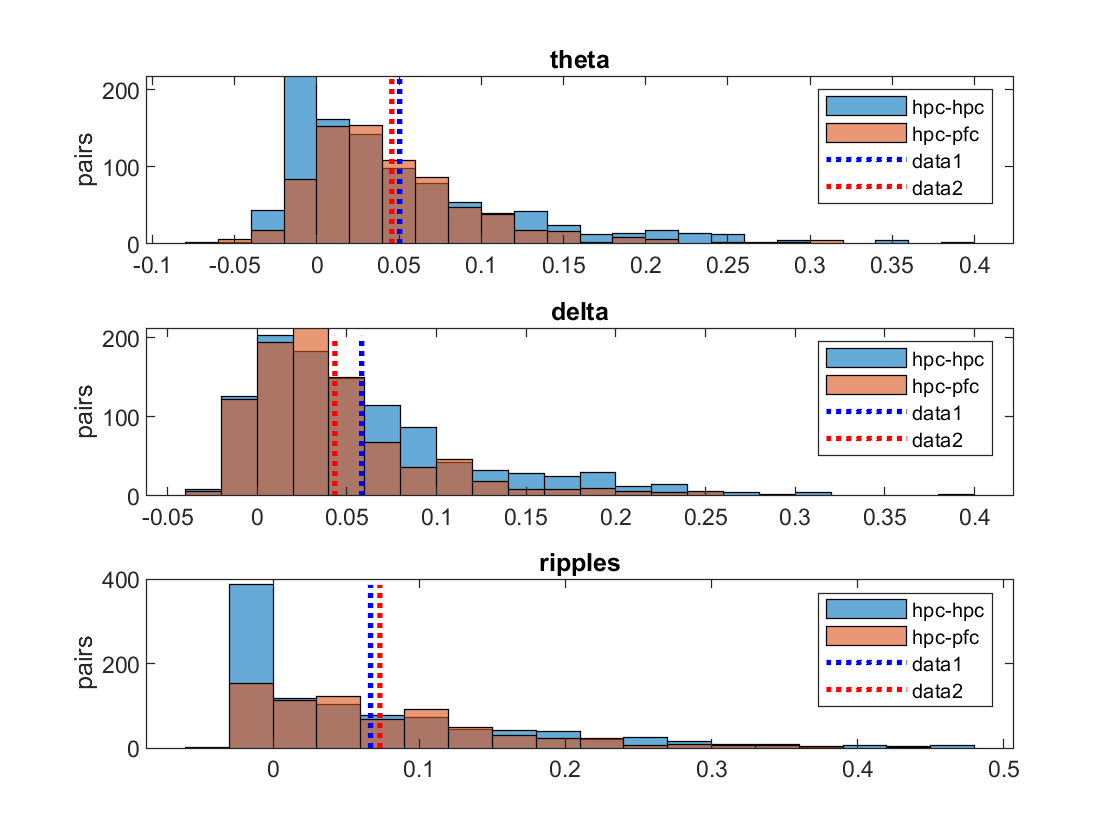

figure(499)
clf
h_corrdiff = zeros(1,nPatterns);
p_corrdiff = zeros(1,nPatterns);
for i = 1:nPatterns
    subplot(3,1,i)
    cofiring_hh = histogram(hh_pairs_patterns(i,:));
    hold on
    cofiring_hp = histogram(hp_pairs_patterns(i,:));
    legend("hpc-hpc","hpc-pfc")
    title(patternnames(i))
    ylabel("pairs")
    
    hold on
    avg_hh=line([mean_hhcorr_pattern(i),mean_hhcorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue'; 
    
    hold on
    avg_hp=line([mean_hpcorr_pattern(i),mean_hpcorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    
     
    [h_corrdiff(i),p_corrdiff(i)] = kstest2(hh_pairs_patterns(i,:), hp_pairs_patterns(i,:));
   
end

the difference in cofiring between hpc-hpc pairs and hpc-pfc pairs are significant for all the activity patterns

% How about just put all the patterns together?
figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(all_pairs_within_hpc)

hist_hh =   Histogram with properties:

             Data: [1×40800 double]
           Values: [1×89 double]
          NumBins: 89
         BinEdges: [1×90 double]
         BinWidth: 0.0100
        BinLimits: [-0.0500 0.8400]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


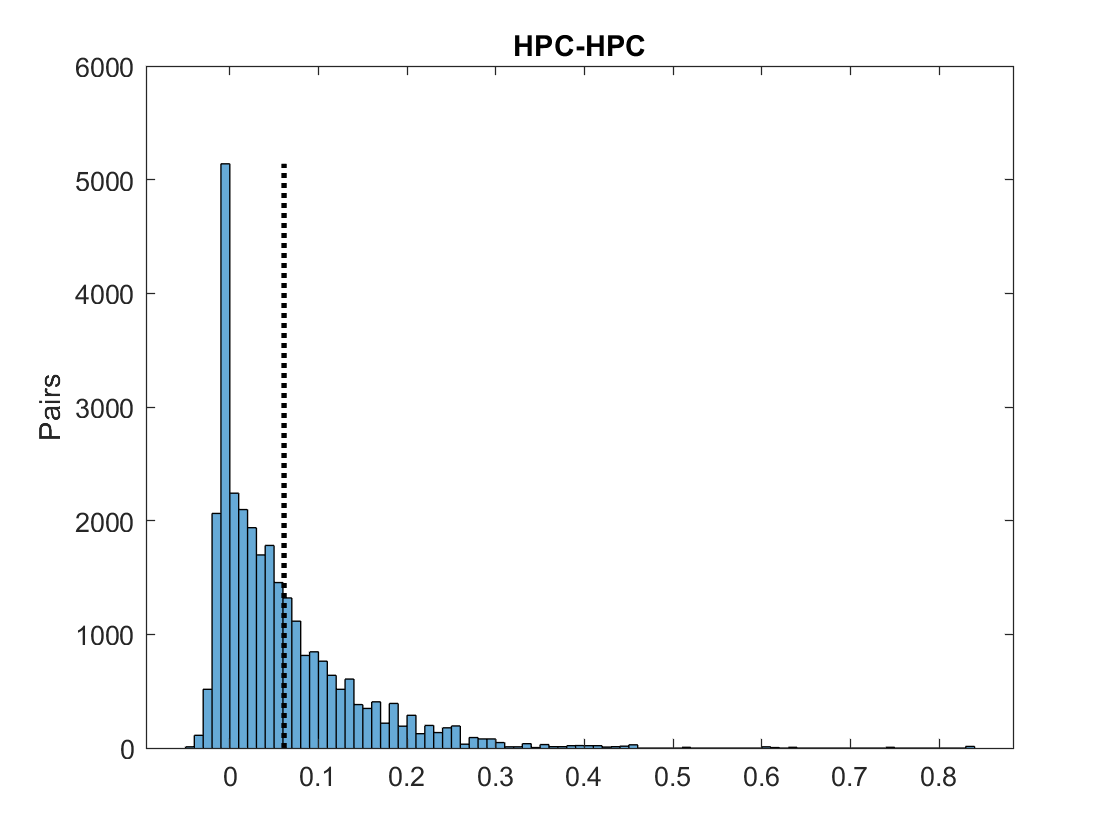

ylabel("Pairs")
title ("HPC-HPC")
example_mean_hhcorr = mean_hhcorr(1);
example_std_hhcorr = std_hhcorr(1);

hold on
lineObject=line([example_mean_hhcorr,example_mean_hhcorr],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(all_pairs_across_regions)

hist_hp =   Histogram with properties:

             Data: [1×40800 double]
           Values: [8 26 50 92 266 1266 2228 2048 2232 2198 2058 1714 1664 1292 1036 952 678 898 610 404 510 242 182 270 144 194 122 162 122 94 92 72 38 78 16 58 48 78 8 10 40 0 62 24 16 0 24 0 0 16 8 14 10 0 22 10 30 8]
          NumBins: 58
         BinEdges: [1×59 double]
         BinWidth: 0.0100
        BinLimits: [-0.0700 0.5100]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


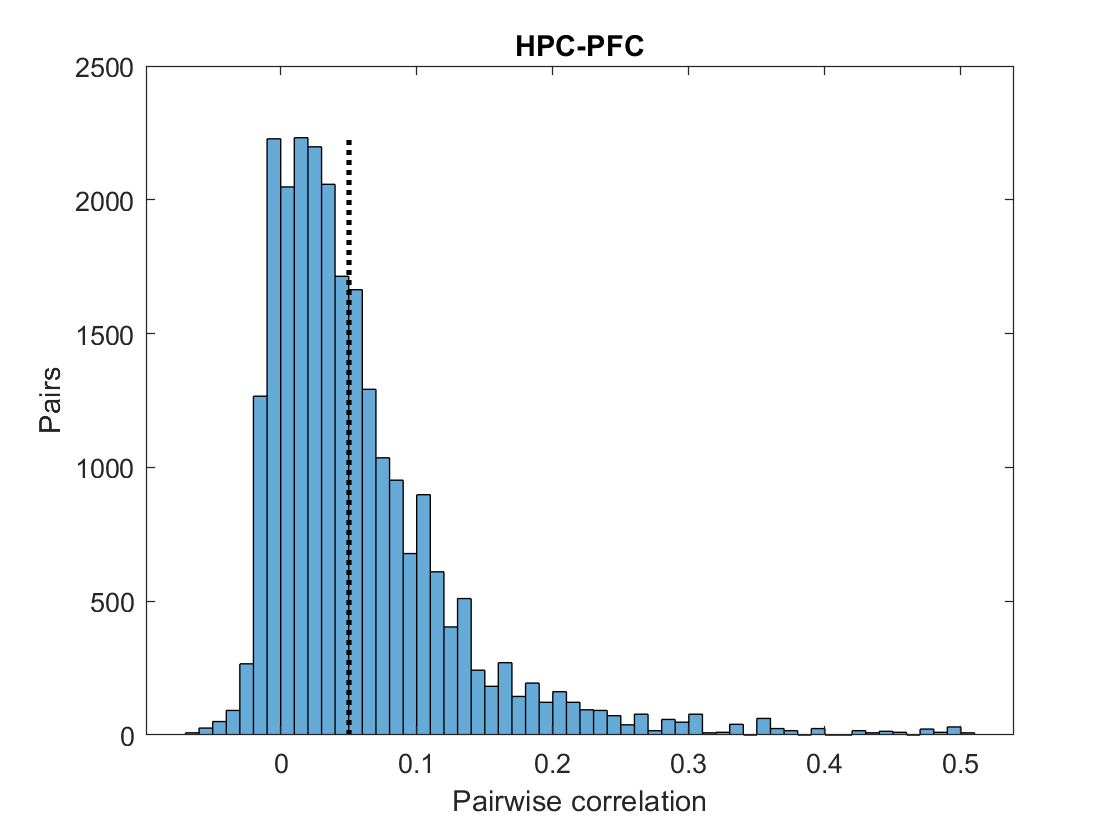

ylabel("Pairs")
title ("HPC-PFC")
example_mean_hpcorr = mean_hpcorr(1);
example_std_hpcorr = std_hpcorr(1);

lineObject=line([example_mean_hpcorr,example_mean_hpcorr],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');

[h_corrdiff,p_corrdiff] = kstest2(all_pairs_across_regions,all_pairs_within_hpc);

% saving meaningful stats and the corresponding Option fields in a csv
cofiring = table(mean(mean_hhcorr), mean(std_hhcorr), mean(mean_hpcorr), mean(std_hpcorr), h_corrdiff, p_corrdiff)

cofiring = 1×6 table
      Var1        Var2        Var3        Var4      h_corrdiff    p_corrdiff 
    ________    ________    ________    ________    __________    ___________

    0.057997    0.057997    0.055671    0.055671      true        2.5466e-140


cofiringRow = table(cofiring, key);

cofiringstats = [cofiringstats; cofiringRow];

save('cofiring', 'cofiringstats')

% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean(mean_hhcorr),mean(std_hhcorr))

ans = "hpc-hpc: 0.058±0.058"

sprintf(formatSpec1,Patterns(2,1).directionality,mean(mean_hpcorr),mean(std_hpcorr))

ans = "hpc-hpc: 0.056±0.056"

disp(p_corrdiff)

  2.5466e-140



Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

load("prediction.mat");
figure(600), clf
% how well a single neuron can predict stuff
all_single_prediction_hh = [];
all_single_prediction_hp = [];

patternPerformance_pfc = zeros(nPatterns, nPartitions); % prediction of
patternPerformance_hpc = zeros(nPatterns, nPartitions);
% useSinglePrediction = true;
for p = 1:nPartitions
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        nSource = size(curr_source,2);
        for d = 1:2
            curr_target = Patterns(p,d,i).X_target';
            for k = 1:nSource
                curr_singleB = Patterns(p,d,i).rankRegress.singlesource_B{k};
                if ~isempty(curr_singleB)
                    curr_singlesource = curr_source(:,k);
                    [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource, curr_target, curr_singleB);
                    if d == 1
                        [all_single_prediction_hh] = [all_single_prediction_hh singlepattern];
                    else
                        [all_single_prediction_hp] = [all_single_prediction_hp singlepattern];
                    end
                end
            end
        end
    end
end
median_singlehh = median(all_single_prediction_hh(~isnan(all_single_prediction_hh)));
temp1 = all_single_prediction_hp(~isinf(all_single_prediction_hp));
temp1 = temp1(~isnan(temp1));
median_singlehp = median(temp1);


r_square_hh = [];
r_square_hp = [];

r_square_hh_patterns = zeros(nPatterns, nTarget*nPartitions);
r_square_hp_patterns = zeros(nPatterns, nTarget*nPartitions);

mean_hhpred_pattern = zeros(1,nPatterns);
mean_hppred_pattern = zeros(1,nPatterns);

for p = 1:10
    for i = 1:nPatterns
        curr_source = (Patterns(p,1,i).X_source)';
        curr_targethpc = (Patterns(p,1,i).X_target)';
        curr_targetpfc = (Patterns(p,2,i).X_target)';
        
        curr_B_hpc = Patterns(p,1,i).rankRegress.B;
        curr_B_pfc = Patterns(p,2,i).rankRegress.B;
        
        [patternhpc, meanhpc] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
        [patternpfc, meanpfc] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
        
        r_square_hh = [r_square_hh patternhpc];
        r_square_hp = [r_square_hp patternpfc];
        
        patternPerformance_hpc(i,p) = meanhpc;
        patternPerformance_pfc(i,p) = meanpfc;
        
        r_square_hp_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternpfc;
        r_square_hh_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternhpc;

    end
  
end

pattern_mean_hh = mean(patternPerformance_hpc,2);
pattern_mean_hp = mean(patternPerformance_pfc,2);

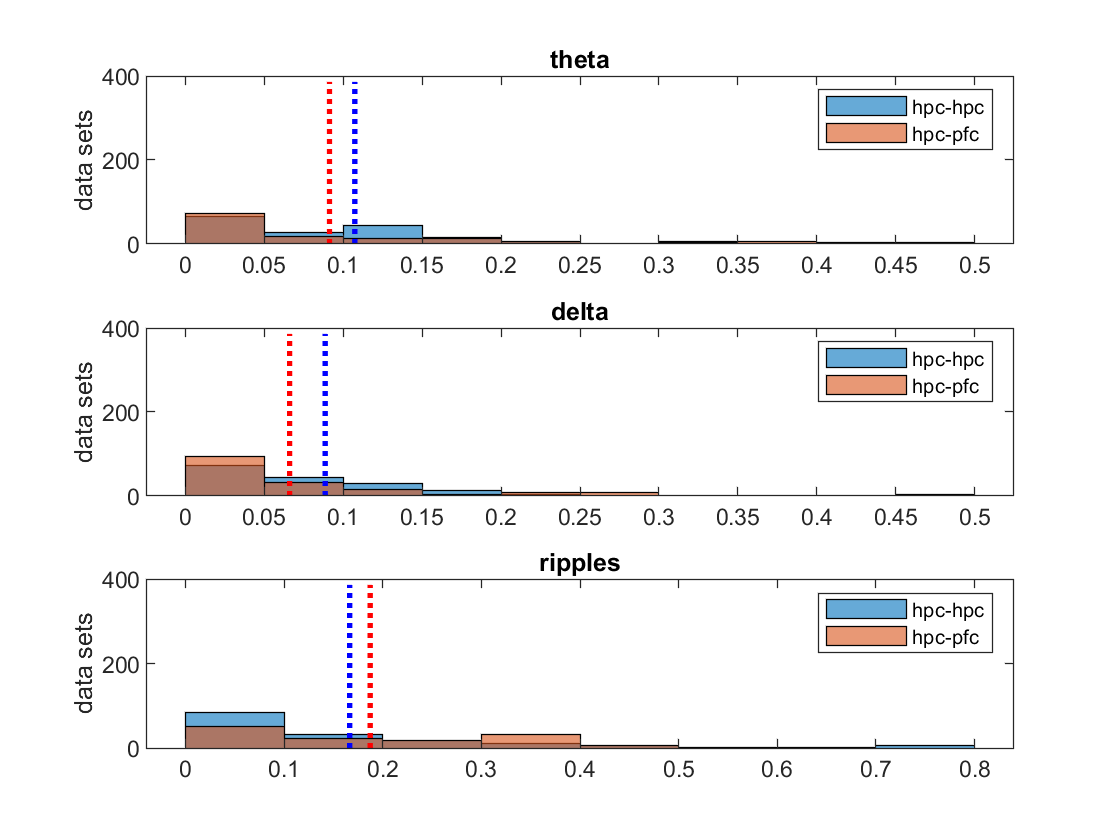

figure(233)
clf
h_pred = zeros(1,nPatterns);
p_pred = zeros(1,nPatterns);
for i = 1:nPatterns
    subplot(3,1,i)
%     curr_hh = r_square_hh_patterns(i,:);
%     temp_hh = curr_hh(curr_hh~=-10000);
%     histogram(temp_hh);
    histogram(r_square_hh_patterns(i,:));
    hold on
%     curr_hp = r_square_hp_patterns(i,:);
%     temp_hp = curr_hp(curr_hp~=-10000);
%     histogram(temp_hp);
    histogram(r_square_hp_patterns(i,:));

    
    hold on
    avg_hh=line([pattern_mean_hh(i),pattern_mean_hh(i)],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue'; 
    
    hold on
    avg_hp=line([pattern_mean_hp(i),pattern_mean_hp(i)],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    
     
    [h_pred(i),p_pred(i)] = kstest2(hh_pairs_patterns(i,:), hp_pairs_patterns(i,:));
    ylabel("data sets")
    title(patternnames(i));
    legend("hpc-hpc","hpc-pfc")
end


mean_hh = mean(r_square_hh(intersect(~isinf(r_square_hh), ~isnan(r_square_hh))));
std_hh  = std(r_square_hh(intersect(~isinf(r_square_hh), ~isnan(r_square_hh))));

mean_hp = mean(r_square_hp(intersect(~isinf(r_square_hp), ~isnan(r_square_hp))));
std_hp = std(r_square_hp(intersect(~isinf(r_square_hp), ~isnan(r_square_hp))));

subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(r_square_hh,25)

hist_hh =   Histogram with properties:

             Data: [1×600 double]
           Values: [134 83 67 58 48 29 15 13 3 7 9 4 7 8 4 5 1 0 0 2 0 1 1 5 1]
          NumBins: 25
         BinEdges: [0 0.0310 0.0620 0.0930 0.1240 0.1550 0.1860 0.2170 0.2480 0.2790 0.3100 0.3410 0.3720 0.4030 0.4340 0.4650 0.4960 0.5270 0.5580 0.5890 0.6200 0.6510 0.6820 0.7130 0.7440 0.7750]
         BinWidth: 0.0310
        BinLimits: [0 0.7750]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


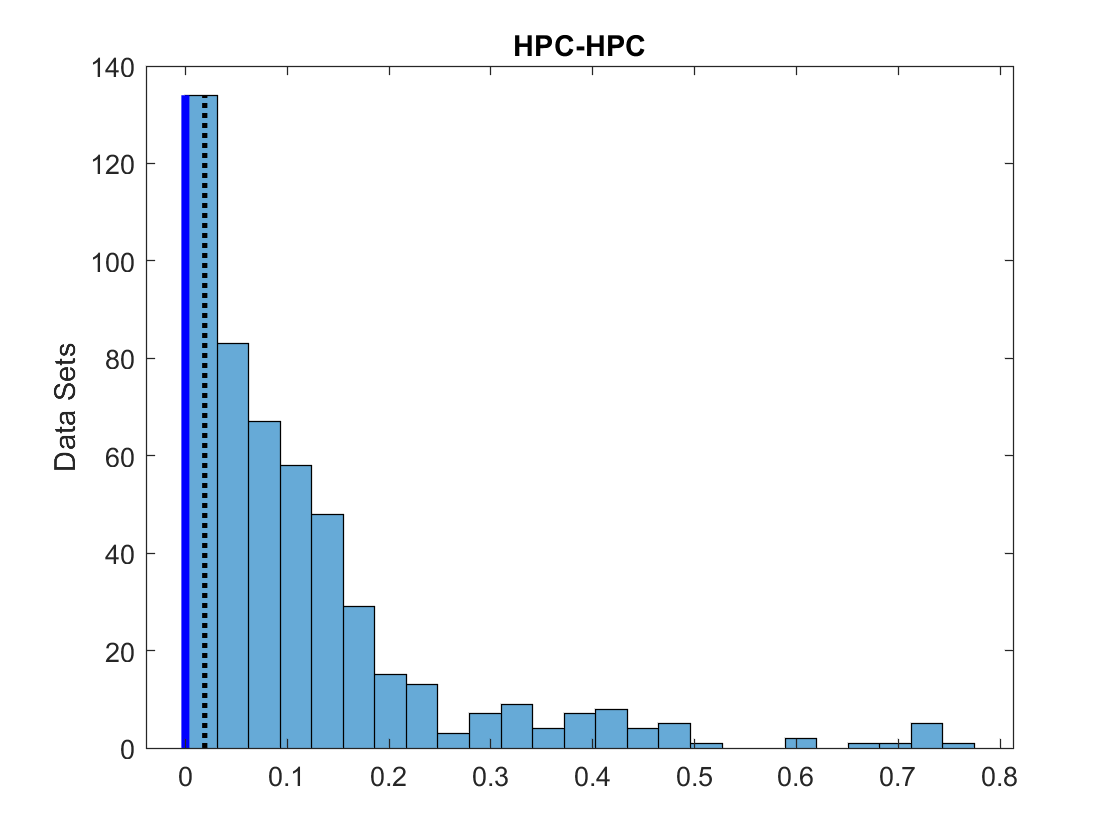

ylabel("Data Sets")
title ("HPC-HPC")
lineObject=line([mean_hh,mean_hh],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

    lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_hh.Values)]);
    lineObject2.LineWidth = 3;
    lineObject2.Color = 'blue';


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_hp,25)

hist_hp =   Histogram with properties:

             Data: [1×600 double]
           Values: [54 110 31 24 21 35 12 12 12 12 8 5 7 6 10 5 8 6 11 10 8 5 2 3 3]
          NumBins: 25
         BinEdges: [0 0.0176 0.0352 0.0528 0.0704 0.0880 0.1056 0.1232 0.1408 0.1584 0.1760 0.1936 0.2112 0.2288 0.2464 0.2640 0.2816 0.2992 0.3168 0.3344 0.3520 0.3696 0.3872 0.4048 0.4224 0.4400]
         BinWidth: 0.0176
        BinLimits: [0 0.4400]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("HPC-PFC")
xlabel("Performance")
linkaxes([ax1,ax2],'x');

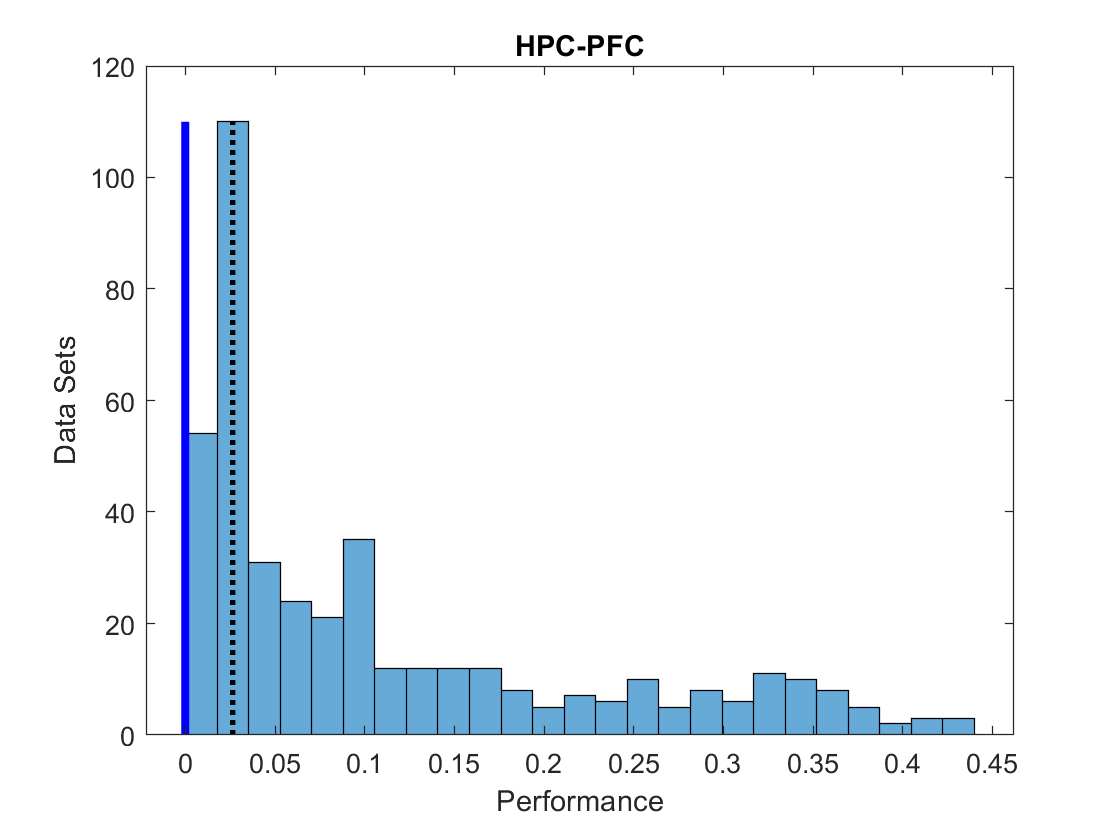

lineObject=line([mean_hp,mean_hp],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

    lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
    lineObject2.LineWidth = 3;  % Thicken the line
    lineObject2.Color = 'blue'; % Color it black

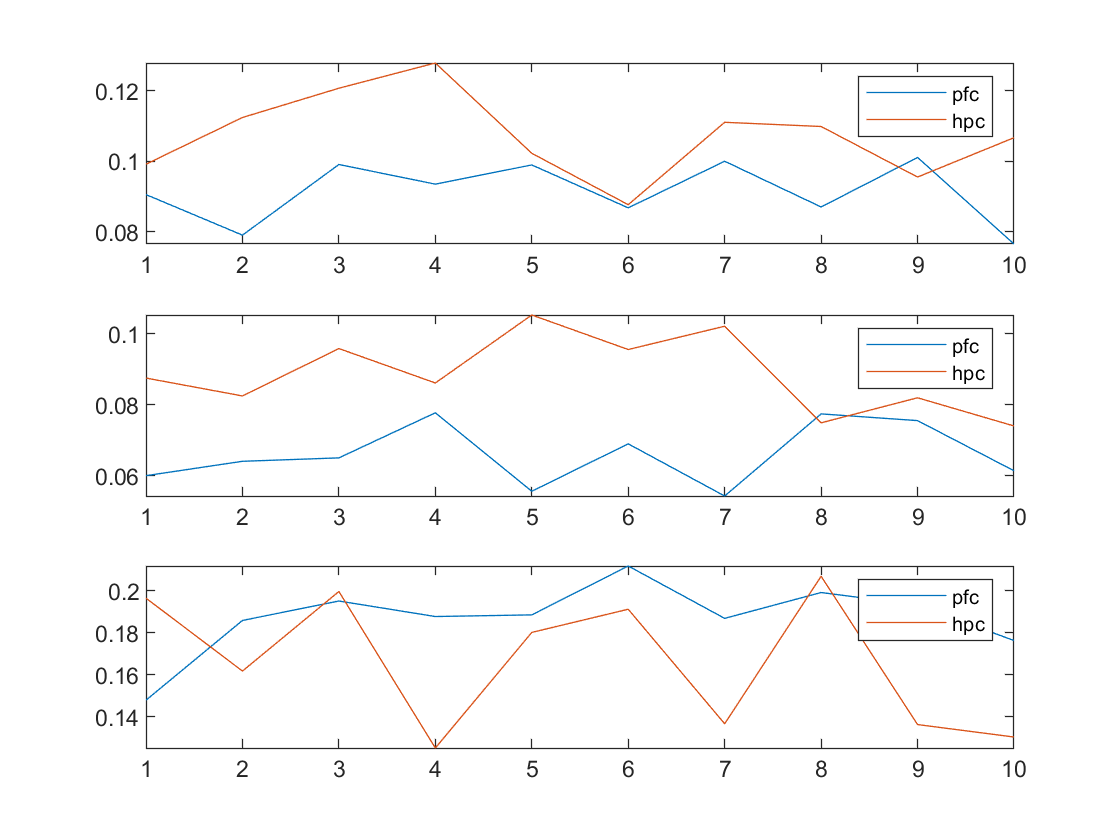

figure(601)
clf
for i = 1:nPatterns
    subplot(3,1,i)
    plot(patternPerformance_pfc(i,:));
    hold on
    plot(patternPerformance_hpc(i,:));
    
    legend("pfc","hpc")
    % how to interpret nans
end


% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_hh, std_hh, mean_hp, std_hp)

Predictiontable = 1×4 table
    mean_hh     std_hh    mean_hp     std_hp
    ________    ______    ________    ______

    0.018957      0       0.026324      0   


predictionRow = table(Predictiontable, key)

predictionRow = 1×2 table
                Predictiontable                    key   
    mean_hh     std_hh    mean_hp     std_hp             
    ________________________________________    _________

    0.018957      0       0.026324      0       "5295fea"


predictionstats = [predictionstats; predictionRow];
save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")

Prediction Performance on Average


sprintf(formatSpec1,Patterns(1,1).directionality,mean_hh,std_hh)

ans = "hpc-hpc: 0.091±0.102"

sprintf(formatSpec1,Patterns(2,1).directionality,mean_hp,std_hp)

ans = "hpc-hpc: NaN±NaN"

if useSinglePrediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)
    
end

single source prediction median


ans = "hpc-hpc: -5.32686e-06"

ans = "hpc-pfc: 4.57062e-04"

## Figure 4

numUsedForPrediction = size(curr_target, 2);
% make the averaged version
curr_cvLoss = cell(10,2,3);
for p = 1:10
    for i = 1:nPatterns
        for j = 1:2  
            curr_cvLoss{p,j,i} = Patterns(p,j,i).rankRegress.cvLoss;
        end
    end
end

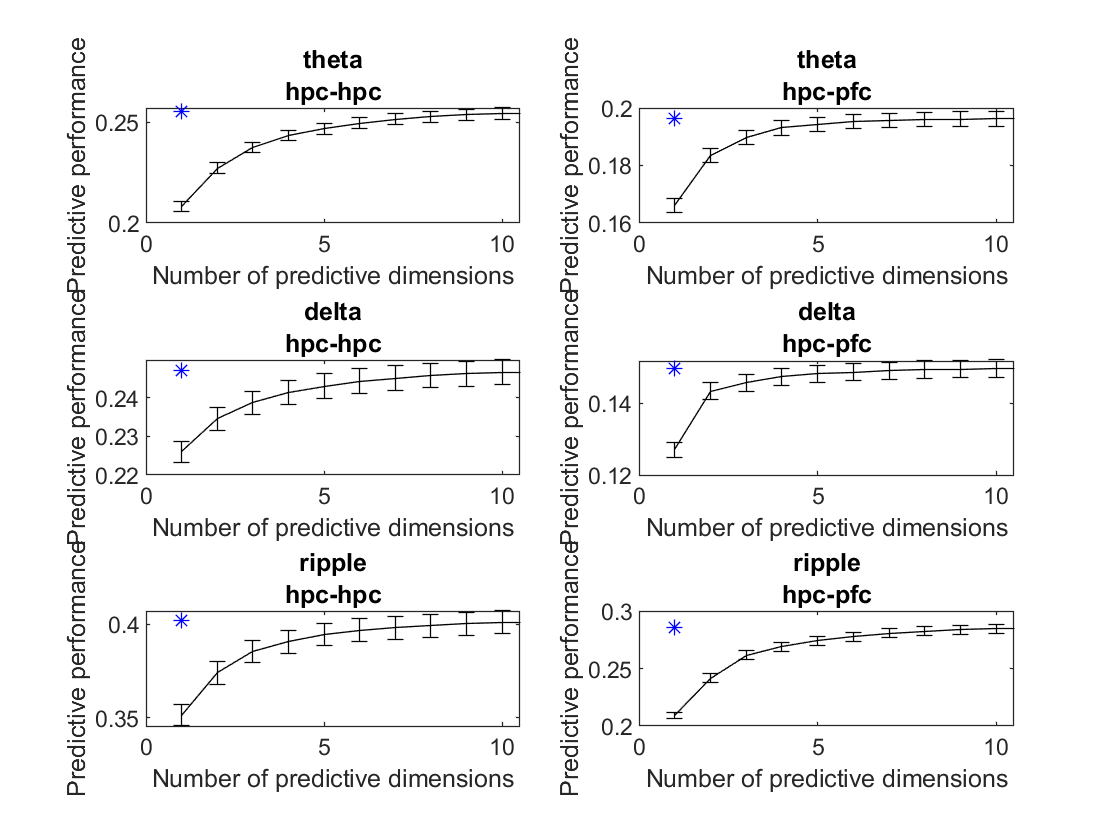

figure(700)
clf
for i = 1:nPatterns
    for j = 1:2
        subplot(3,2,2*(i-1)+j)
        full_model = plots.plotPredictiveDimensions(numUsedForPrediction,curr_cvLoss(:,j,i));
        xlim([0,10.5])
        hold on

        plot(1, full_model,'b*');
       
        title([Patterns(p,j,i).name Patterns(p,j,i).directionality])
    end
end

#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

result = query.getHashed("winSize", "pre: -0.2 post: 0.2", "generateH", "fromFilteredEEG")

result = 6×11 char array
    '0876f4c.mat'
    '2b6bed4.mat'
    '4044dbe.mat'
    '45ff5f1.mat'
    '5295fea.mat'
    'f1876f1.mat'


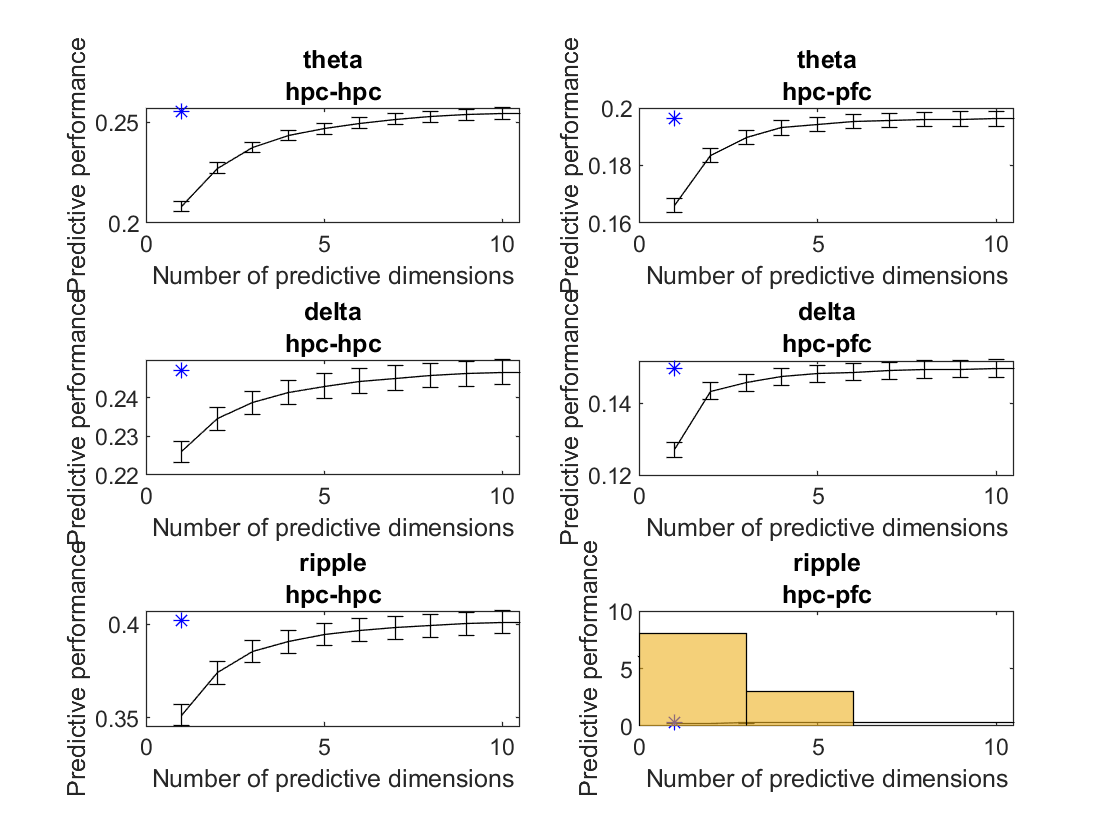



numResultsToExamine = size(result,1);
ratios = zeros(3,numResultsToExamine);
hpcDims = zeros(3,numResultsToExamine);
pfcDims = zeros(3,numResultsToExamine);

for i = 1:numResultsToExamine
%     currPatterns = table2array(table2array(result(i,2)));
%     currPatterns = reshape(currPatterns, [10,2,4]);
    
    load(result(i,:))
    
    temp1 = zeros(3,nPartitions);
    temp2 = zeros(3,nPartitions);
    temp3 = zeros(3,nPartitions);
    for j = 1:nPartitions
        for k = 1:nPatterns
            temp2(k,j) = Patterns(j,1,k).rankRegress.optDimReducedRankRegress;
            temp3(k,j) = Patterns(j,2,k).rankRegress.optDimReducedRankRegress;
            temp1(k,:) = temp2(k,:)./temp3(k,:);
        end
        
    end
    
    ratios(:,i) = mean(temp1,2);
    hpcDims(:,i) = mean(temp2,2);
    pfcDims(:,i) = mean(temp3,2);
end



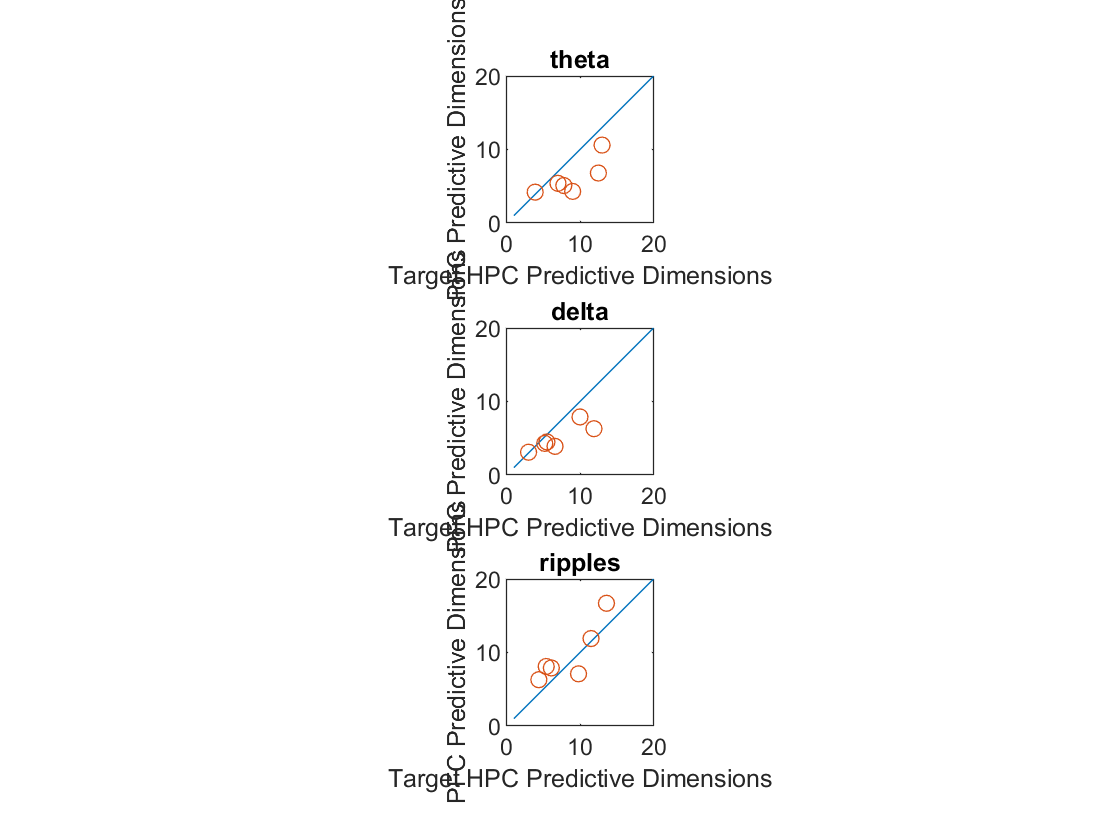


figure(800)

clf
for i = 1:nPatterns
    subplot(3,1,i)
    x = 1:nTarget;
    plot(x,x)
    hold on
    scatter(hpcDims(i,:), pfcDims(i,:));
    ylabel("PFC Predictive Dimensions")
    xlabel("Target HPC Predictive Dimensions")
    title(patternnames(i))
    axis square
end

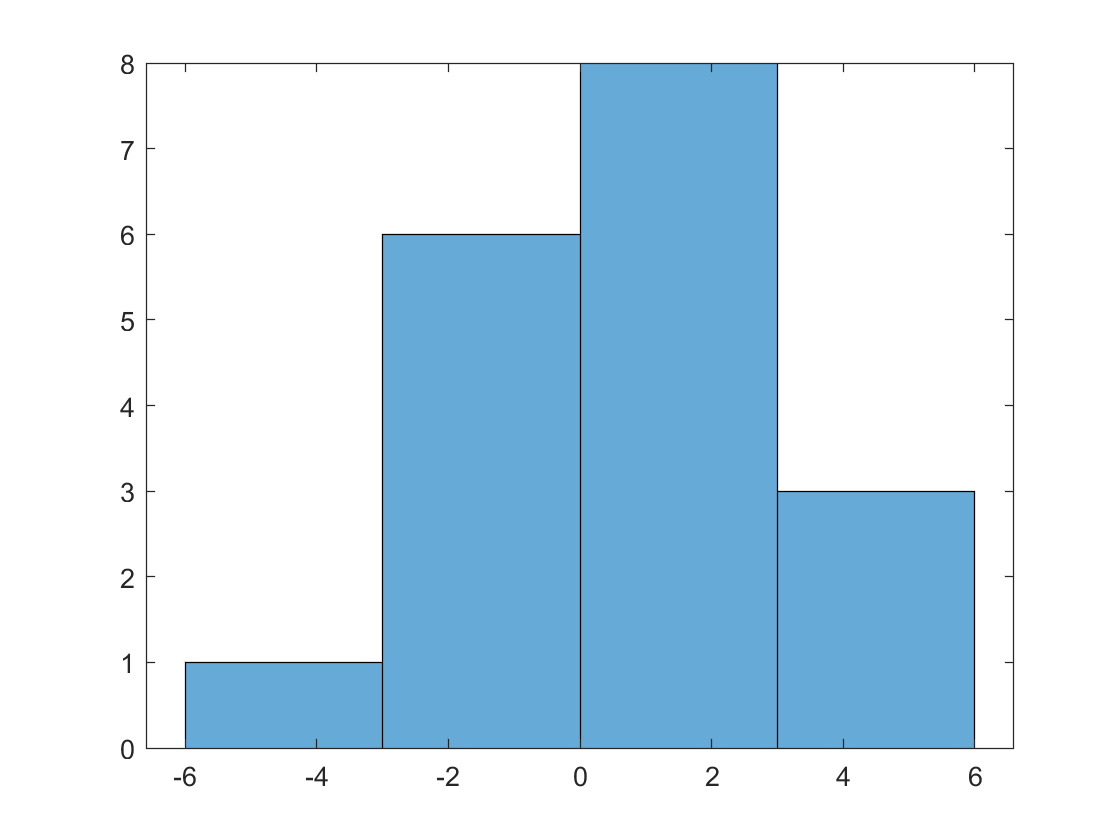

figure (801)
diff = hpcDims-pfcDims;
histogram(diff)